- Function **imshow** shows the image, using the right axis ratio and original graylevel scale of the image.

- **image** uses Matlab’s method for displaying matrices as images. It uses the graylevel scale of the image, but it does not use the right axis ratio.

- **imagesc** works just as image but rescales the graylevels to use the full colormap.

I = imread('napoleon.png');


# 2) 

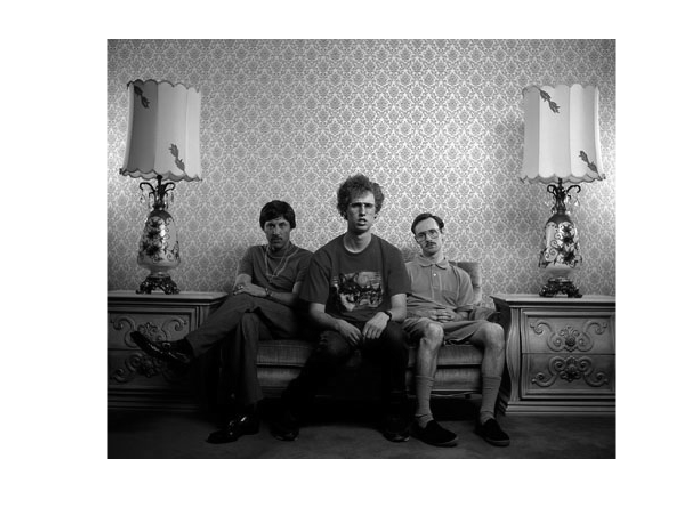

I = imread('napoleon.png'); % read the image
imshow(I); % show image I using ’imshow’
figure % open a new figure window
image(I) % show image I using ’image’
colorbar % add a colorbar showing the colormap
figure % open a new figure window

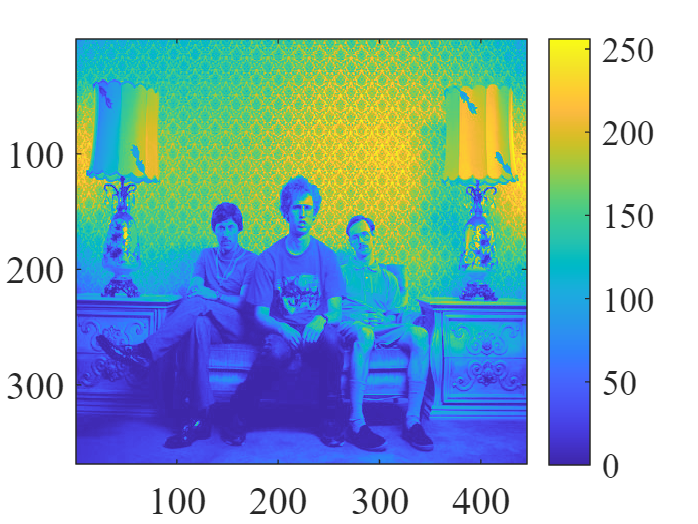

imagesc(I) % show matrix I using ’imagesc’
colorbar % add a colorbar


imwrite(I,'my_napoleon.png') % write image I to file ’my_napoleon.png’


#### Q.1 Where in the image is the pixel (1, 1) located and what is the graylevel value? In

#### command window type `I(1,1)`. Did you get the same value?

imtool(I)

I(1,1)

***ANS:*** Pixel (1,1) is located in the top left corner and has the value 89. Using the command (1,1) results in 89. 

# 3) Contrast, Brightness and Datatypes

I = imread('napoleon.png');
L = imread('napoleon_light.png');
D = imread('napoleon_dark.png');


imtool(I)
imtool(L)
imtool(D)

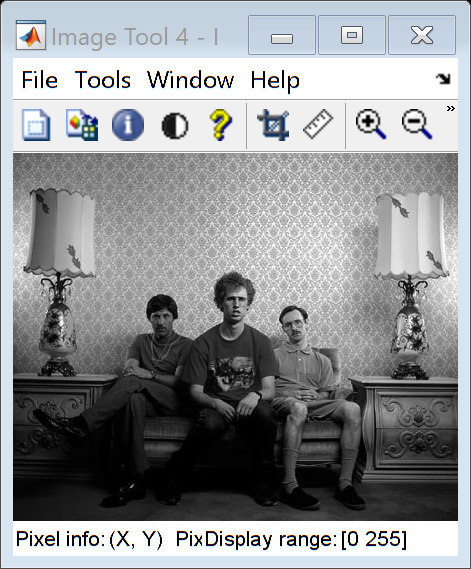

x = imabsdiff(I,L);
y = imabsdiff(I,D);
imshowpair(x,y,'montage')
mean2(D) % mean of all elements in D
imshow(imadd(I,L))

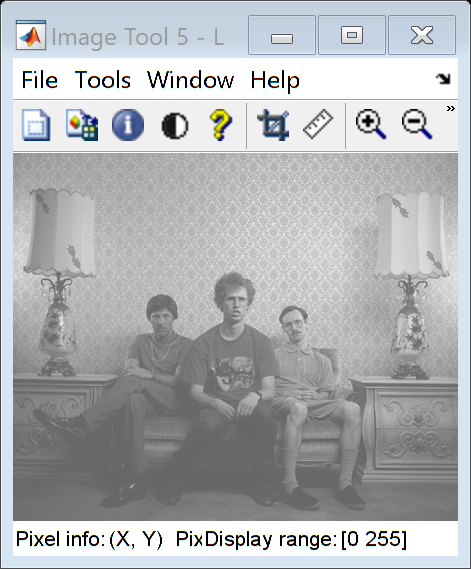

imshow(I+L)

#### Q.2 Explain what contrast and brightness are and include figures of the histograms of the images napoleon.png, napoleon light.png, and napoleon dark.png. Can you tell from the histograms which figure has the highest contrast and which figure is the brightest?

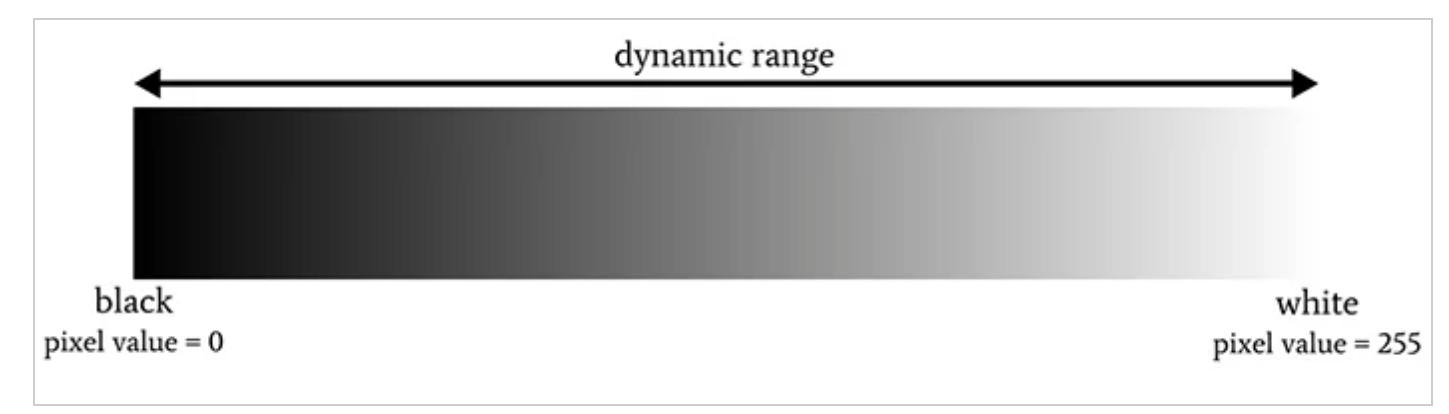

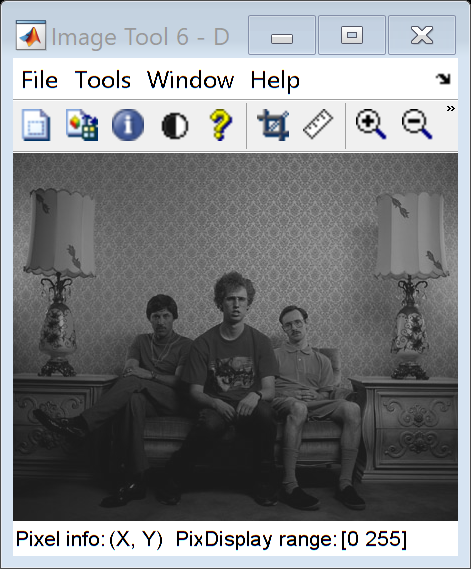

% Plot the histograms 


imhist(I) % show the histogram of I (nap. original)
imhist(L) % show the histogram of L (nap. light)
imhist(D) % show the histogram of D (nap. dark)
dynrange_I = max(I(:)) - min(I(:))
dynrange_L = max(L(:)) - min(L(:))
dynrange_D = max(D(:)) - min(D(:))

***ANS:*** 

- **Contrast** is the difference in dynamic range (lowest value to highest value) of color or grayscale intensity in an image.  

- **Brightness** is a relative term, which is how we perceive the amount of light in a picture. 

- The historigrams shows the grayscale intensity distrubution of the images, and the historigram of **L **is shifted to the right and shows the lowest amount of low intensity grayscale out of the three => Probably the one with the **highest** perceived brightness.

- historigram of **D** shows the least amount of high intensity grayscale out of the three => Probably the one with the **lowest** perceived brightness.

- Historigram of **I** shows nonzero intensity going from 0 to 255, hence it has the **highest contrast**, the other two, **L** and **D** have half the contrast of **I**.

whos % explore workspace
class(I) % show the datatype of I (uint8)

Is = single(I); % Convert from uint8 to single
image(Is)
imtool(I) % This looks OK!
imtool(Is) % This looks strange!
imtool(Is/255) % This looks OK!
IL = I/64;


  Name               Size               Bytes  Class                              Attributes

  F                256x256            1048576  double                             complex   
  I                256x256              65536  uint8                                        
  I1                 1x1                    8  matlab.graphics.primitive.Image              
  IL               256x256              65536  uint8                                        
  Iblur3           256x256              65536  uint8                                        
  Is               256x256             262144  single                                       
  Is_1               1x1                    8  matlab.graphics.primitive.Image              
  Jbf               78x78                6084  logical                                      
  Jbt               78x78                6084  logical                                      
  Jnf               78x78                6084  logical               

#### Q.3 Explain the difference of `imagesc((I/64)*64)` and `imagesc((Is/64)*64)`, where `I` is `uint8 `and `Is` is `single`.

image(I) % original image (uint8)

ans = 'uint8'

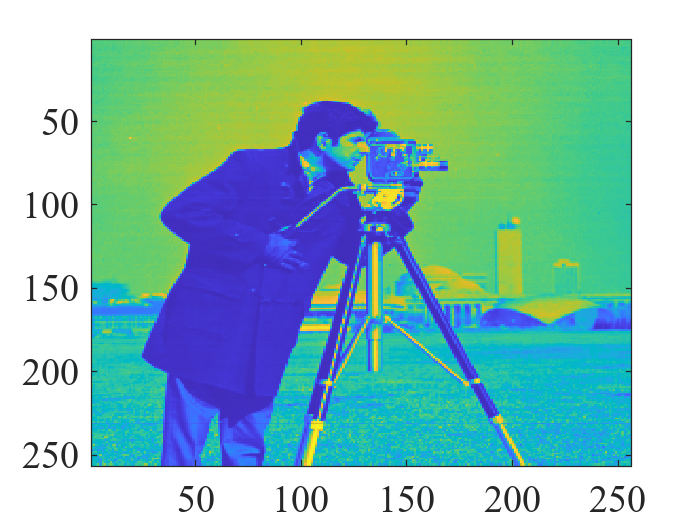

Is_1 = imagesc((Is/64)*64) % (type: single) scaled and rescaled of single precision
I1 = imagesc((I/64)*64) % scaled and rescaled back to original


***ANS:*** 

- I/64 results in a matrix of decimals that are rounded to the nearest integer and therefore information is lost. The image now has  intensity values in the interval [0,4]. Upscaling it back therefore results in loss of detail from the initial rounding and all intensities that have value 4 becomes 4*64 = 256, which results in white.

- Using Is_1 = imagesc((Is/64)*64) we get a image with the same number of pixels. we first scale it down by a factor 64 and then scale it up by the same factor. The scaling and rescaling has not affected the quality of the image in any major way. This is because the image was of type single precision and so the decimal values have caused a minimal loss of information.

#### Q.4 Demonstrate a mathematical expression involving `I `to make it brighter.

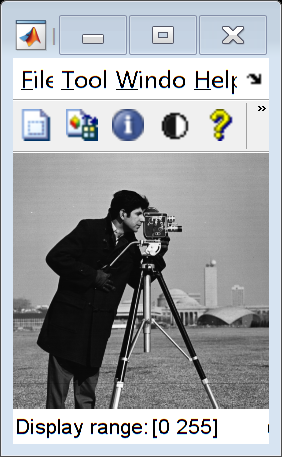

const = 15

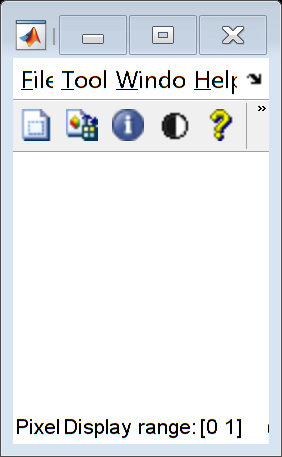

imshow(I+const)

***ANS:***  To make the figure brighter: `I+C, `where c is a constant > 1

#### Q.5 Demonstrate a mathematical expression involving `I` to give it lower contrast

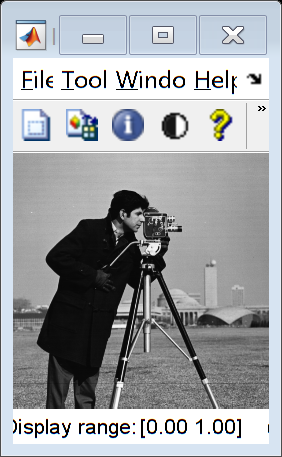

const = 0.45

imshow(I*const)

***ANS:***  To make the contrast lower: `I*C, `where c is a constant < 1

# 4)

I = imread('napoleon.png');

ans = uint8
4

imhist(I);
imshow(I)

#### Q.6 Use g = 2 and g = `1/2` and explain the resulting images.

Gamma transformation:


$$C*{f\left(x,y\right)}^{\gamma \;}$$


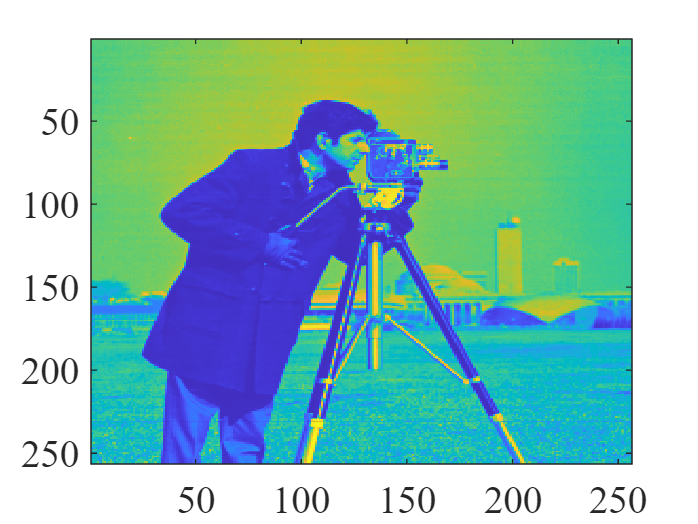

g1 = 3

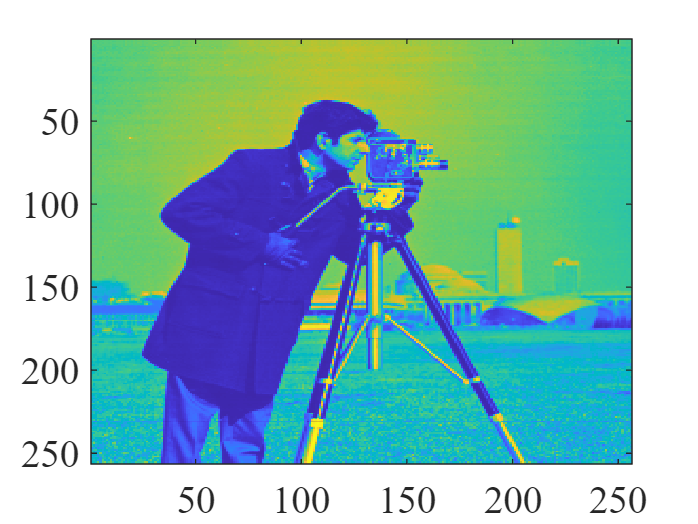

Is_1 =   Image with properties:

           CData: [256×256 single]
    CDataMapping: 'scaled'

  Show all properties


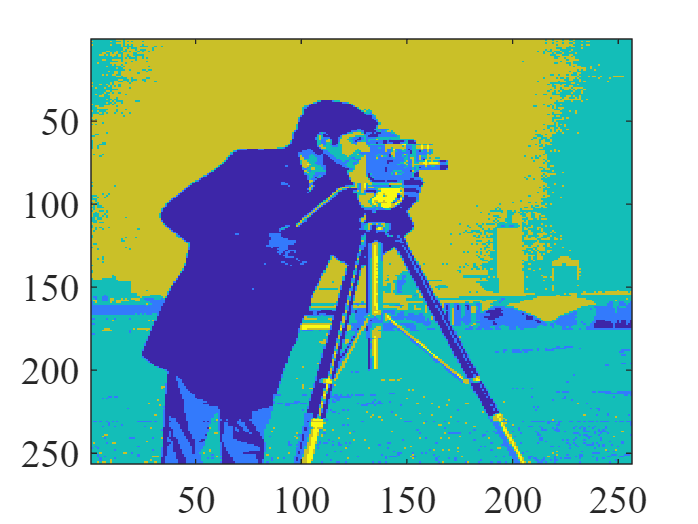

I1 =   Image with properties:

           CData: [256×256 uint8]
    CDataMapping: 'scaled'

  Show all properties


% max(max(L1)) = max(L1(:))

L1 = double(I).^g1;
out1 = uint8(L1 .* (255/max(max(L1))));
imhist(out1);
imshow(out1)
meangrey1 = mean2(out1)
g2 = 1/2

L2 = double(I).^g2;
out2 = uint8(L2 .* (255/max(max(L2))));
meangrey2 = mean2(out2)
imhist(out2);
imshow(out2)


***ANS:***

Gamma is determined by where we anchor white (max luminance). For  g = 2 , the resulting image has a higher brightness than what we see for g = 1/2. Thus, increasing gamma decreases the average greylevel of the image, and vice versa.

#### Q.7 Explain how histogram equalization works in theory. Include histograms of one of the images before and after applying equalization in your report and explain what you see. Do the changes to the histograms and the images agree with the theory of histogram equalization?

I = imread('napoleon.png');
imhist(I)
J = histeq(I);
imhist(J) % After histogram equalization

imshow(I) % Before equalization
imshow(J) % After equalization



***ANS:*** In theory the histogram equalization works by evenly distribute the gray-levels for  visual contrast enhanecment. We can see that after the equalization, the graylevels are more evenly spread out on the range [0,255], giving a higher contrast and making details more distinguisable.

# 5)

% I = imread('zebra.png');
I = imread('cameraman.png');
imshow(I)
Jnf = imresize(I, [78 78], 'nearest', 'antialiasing', false);
imshow(Jnf)
Jnt = imresize(I, [78 78],'nearest', 'antialiasing', true);
imshow(Jnt)
Jbf = imresize(I, [78 78], 'bilinear', 'antialiasing', false);
imshow(Jbf)
Jbt = imresize(I, [78 78], 'bilinear', 'antialiasing', true);
imshow(Jbt)


#### Q.8 Explain the role of the interpolation method as well as the role of the lowpass-filter. Which combination of options do you prefer? And why?

***ANS:***

The role of the interpolation method according to Matlab help function:

"Nearest-neighbor interpolation; the output pixel is assigned the value of the pixel that the point falls within"

"Bilinear interpolation; the output pixel value is a weighted average of pixels in the nearest 2-by-2 neighborhood"

- The role of the interpolation method is to smooth the image (dampen "jagged" image content).

- The role of the lowpass-filter is to attenuate high frequency content while leaving the low frequencies unaltered.

#### Q.9 Can you give a real-life example of aliasing outside the area of image analysis and signal processing in general? Have you seen this phenomenon before?

***ANS:***

For example the rotating blades of a helicopter can appear to rotate slowly in the opposite direction while in actuality the rotational speed is very high and in the other direction. The same example can be a spinning wheel of a car..

# 6)

brain1 = imread('brain1.png');
brain2 = imread('brain2.png');
brain3 = imread('brain3.png');
imshow(brain1)

#### Q.10 How can a “standard” healthy brain, or a mean image, of the two images brain1.png and brain2.png be constructed? In your report include a figure showing the standard brain.

standardBrain = imadd(double(brain1),double(brain2))/2; % (naive way) mean image "standardBrain"
imshow(uint8(standardBrain),[]) %standardbrain

% More resonable way to get a mean image
standardBrain = imabsdiff(brain1,-brain2);

imshow(standardBrain,[]) 

***ANS:*** Plot of the mean brain ("standard" helathy brain) -->

#### Q.11 Find the difference between the “standard” brain and the image from the stroke patient (brain3.png). Where in the brain is the change located?

changeBrain = (standardBrain-brain3); % will involve clipping
changeBrain2 = imabsdiff(standardBrain,brain3); % absolute difference
imshowpair(changeBrain,standardBrain,'montage')


***ANS:*** The change in the stroke brain seems to be in the **top right area of the brain** 

#### Q.12 What happens when a pixel gets a value less than 0 or a value greater than 255? Are there other ways this can be handled? Did you think of this when you computed the “standard” brain in the previous exercise?

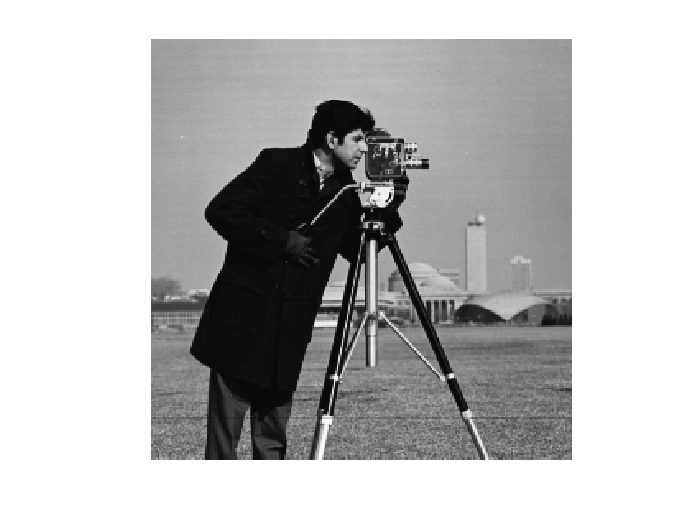

test = brain1 + 100
test2 = brain1 - 100

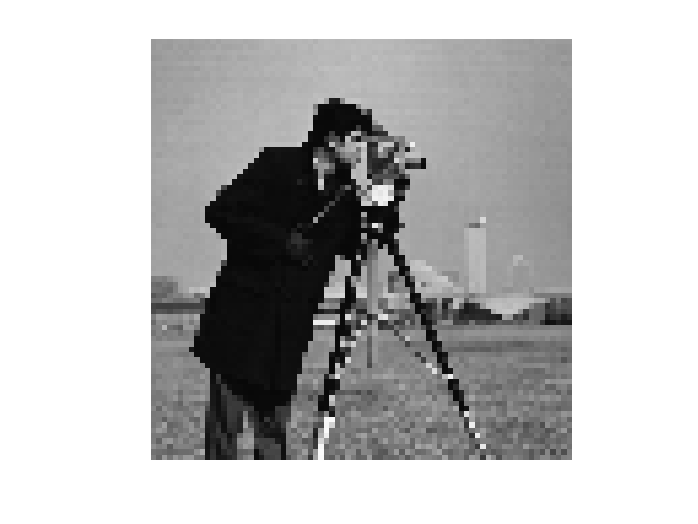

test3 = abs(brain1 + 100) % same as test
imshow(test)

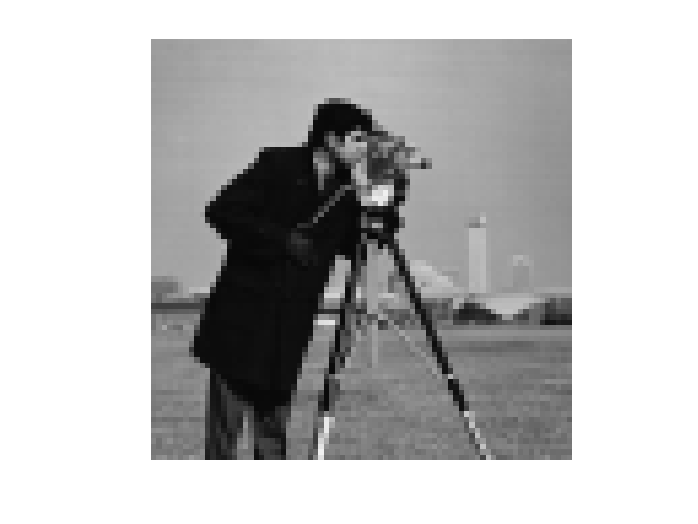

imshow(test2)
imshow(test3)

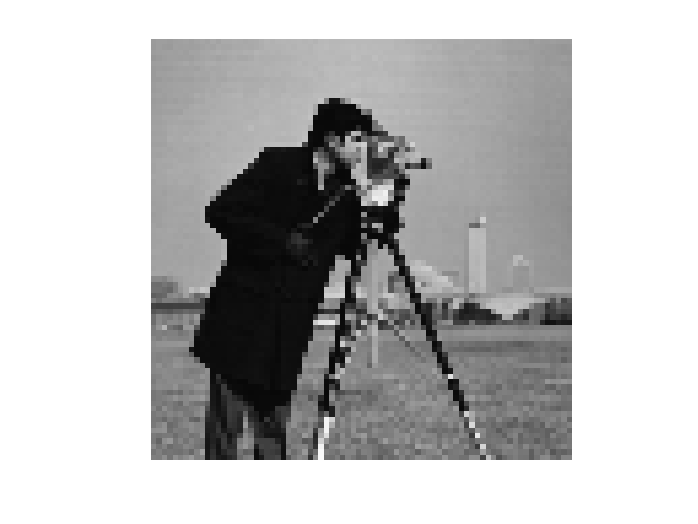

test == test3;% true


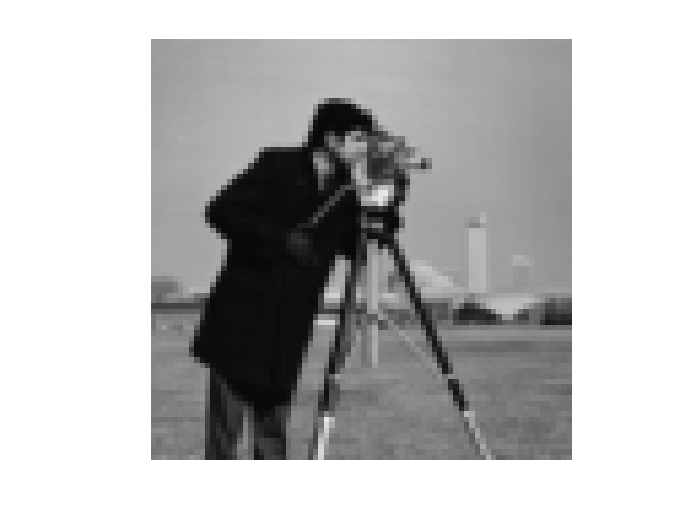

% handle the clipping using imabsdiff(I1,I2):
I_100 = 100.*(ones(size(brain1),'uint8')); % array of value 100

Z = imabsdiff(brain1,test5)
imshow(Z)

***ANS:*** If the value of a pixel becomes grater than 255 or less than 0 the value will be capped at 255 and 0 respectively. One way to handle it could be to take the absolute difference between each element of brain1 and I_100 using Z = imabsdiff(I1, I2).

Which Matlab defines as: "[`Z`](https://se.mathworks.com/help/images/ref/imabsdiff.html#buxpnjq-1-Z) `= imabsdiff(`[`X`](https://se.mathworks.com/help/images/ref/imabsdiff.html#buxpnjq-1-X)`,`[`Y`](https://se.mathworks.com/help/images/ref/imabsdiff.html#buxpnjq-1-Y)`)` subtracts each element in array `Y` from the corresponding element in array `X` and returns the absolute difference in the corresponding element of the output array `Z"`

# 7)

I = imread('wrench.png')
J = imrotate(I,20);
K = imrotate(I,20,'bilinear');
imshow(I)
imshow(J)
imshow(K)

#### Q.13 Compare rotations performed with and without interpolation. It is easiest to see differences along lines and edges of the images. What does interpolation mean in this case?

***ANS:*** Interpolation in this case means smoothing of the jagged edges that comes from rotation of the image.

#### Q.14 In general it is faster to rotate the image by a multiple of 90 degrees than by some arbitrary degree. Explain why. For this task use Matlab functions tic and toc.

I = imread('wrench.png');

time90 = zeros(1,100);
time53 = zeros(1,100);
for i = 1:100
    tic
    J = imrotate(I,90);
    time90(i) = toc;
    
    tic
    J = imrotate(I,53);
    time53(i) = toc;
end 

% Mean time of rotating the figure with 90 and 53 degrees
degrees_90 = mean(time90)
degrees_53 = mean(time53)
min(degrees_53,degrees_90)

***ANS:*** It is because rotation rotating an image by a multiple of 90 degrees is done by matrix rotation. I.e., rotating image 90 deg => rotate the matrix by 90 deg, which does not require much time for vectorized computations. Example for 90deg and 180 deg: 

A = [1 2; 3 4]
Arot90 = rot90(A)
Arot180 = A(end:-1:1,end:-1:1) % = rot90((rot90(A)))
Arot180 = rot90((rot90(A)))


# 8 Scripting and Looping

## Q.15 - Mean filtering

• Load the image.

• Convert the image to grayscale using e.g. rgb2gray.

• Resize and/or crop your image to 128×128 pixel size, without changing the aspect ratio of the image.

• Loop (!) over the image using a 5×5 pixel window. For each such window, compute the average pixel value and store the result in a new image. Treat borders in some controlled way and make sure the result has the same size in pixels as the original image. You will need at least two nested for-loops, to scan rows and columns in your image.

• Subtract the original image from your new filtered image.

• Present the original, filtered and subtracted images in a figure, using e.g. subplot.

clear
clc

I = imread("parrot.jpg"); % 1000x1000 pixels RGB
imshow(I)
I = rgb2gray(I);            % Convert RGB -> Grayscale
I = im2double(I);           % Convert form uint8 to double
I = imresize(I,[128 128]);  % resize to 128x128 pixels
sz = size(I);               % 128x128
orig_image128 = I;

% Define the window size: 5x5
windowdim = [5 5]; % rows cols
% Determine size of zero padding to handle borders of the image:
padsize=floor(windowdim/2); % pad with two zeros around the image

% Add zero padding around the image: 128x128->132x132
paddedimage = padarray(I,padsize,0,'both'); %132x132

% Create array to store the filtered image in:
Filtered_image = zeros(sz,class(I));
% specify offsets based on size of the window
offset_rows = windowdim(1)-1; % = 4
offset_cols = windowdim(2)-1; % = 4
% Loop through the rows and columns, computing the mean of the window
% sized block of the padded image:
for row=1:sz(1)
	for col=1:sz(2)
        % Calc mean of 5x5 sample window
		window_region = paddedimage(row:(row+offset_rows),col:(col+offset_cols));
        % Store the mean value of the window region in the filtered image:
		Filtered_image(row,col) = mean2(window_region(:));
	end
end

% Subtract the original image from new filtered image:
Isubtracted =  Filtered_image - orig_image128;
figure();
montage({orig_image128, Filtered_image, Isubtracted})
title("Original image (top left), Filtered image (top right), Subtracted image (lower left)")

% Iorig2 = im2uint8(orig_image128);
% Filtered_image2 = im2uint8(Filtered_image);
% Isubtracted2 = im2uint8(Isubtracted);
% 
% montage({Iorig2, Filtered_image2, Isubtracted2})
% title("Original image (top left), Filtered image (top right), Subtracted image (lower left)")



## Q16 - Histogram equalization

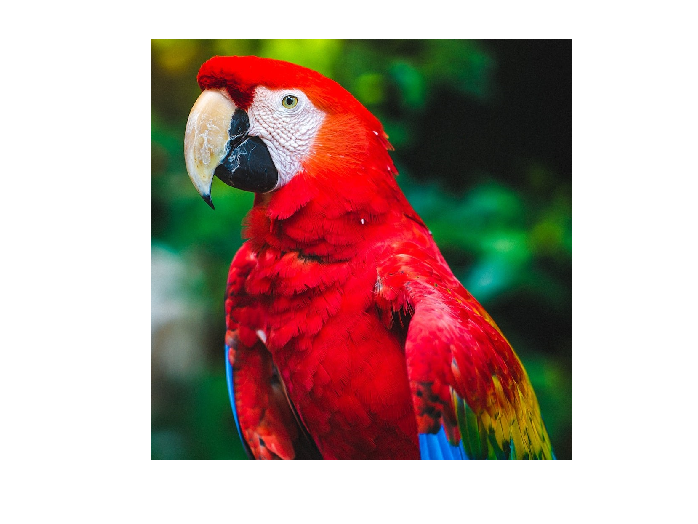

clear
clc

original_image = imread("parrot.jpg"); % 1250x1000 pixels RGB
gray_image = rgb2gray(original_image); % Convert RGB -> Grayscale


histEQ_image = myhist(gray_image);  % use created myhist function


% Plot the images
subplot(3,3,2)
imshow(original_image)
title('Original image')

subplot(3,3,4)
imshow(histEQ_image)
title('HyhistEQ image')

subplot(3,3,5)
imshow(gray_image)
title('Original grayscale')

subplot(3,3,6)
imshow(histeq(gray_image))
title('Matlab histeq()');

function Inew = myhist(I)
    image = I;

    [row_sz, col_sz] = size(image); % row and column size of image
    tot_pixels = row_sz*col_sz; % total nr of pixels in image
    
    Inew = uint8(zeros(row_sz, col_sz));  % zero matrix for the resulting image
    
    frequency = zeros(1, 256);   % freq 0-255
    

    %create histogram of graylevels
    for i=1:row_sz

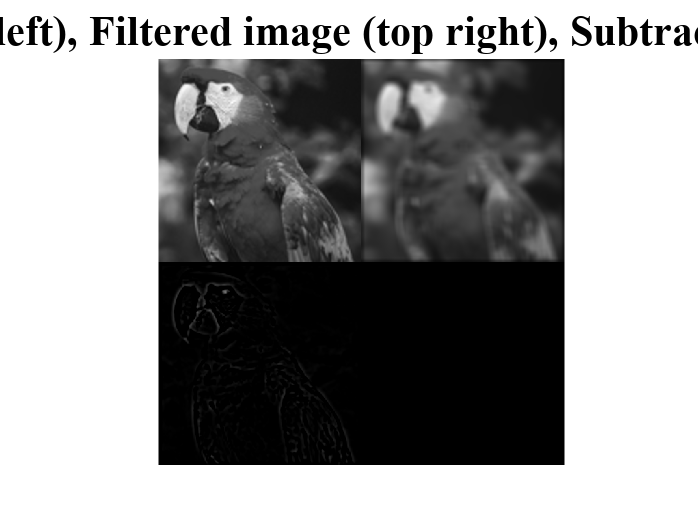

        for j=1:col_sz

            value = image(i,j) + 1;  % +1 to shift the 0-255 values to match our 1-256 freq array.
            frequency(value) = frequency(value)+1;
        end
    end 
    
    cumulativ = cumsum(frequency);
    cumulativ_dist_fun = cumulativ/tot_pixels;
    T = round(cumulativ_dist_fun * 255);   % create the look-up table for which the original values will transform to. 
    
    % create the new image with the transfer function T
    for i=1:row_sz
        for j=1:col_sz
            Inew(i,j) = T(image(i,j) +1);
        end 
    end
end 